close all
clear
clc

定义原系统

A = 1e5;
alpha = 1e3;
As = tf(A*alpha,[1 alpha]);

定义反馈通路

beta = 1e-4;
Fs = tf(beta,1);

将原系统作为前向通路，定义新系统

Hs = feedback(As,Fs);

分别计算两个系统的频率响应

omg = logspace(0,5,100);
Aomg = freqs(As.num{:},As.den{:},omg);
Homg = freqs(Hs.num{:},Hs.den{:},omg);

定义仿真时刻和激励信号

t = 0:1e-5:5e-2;
x = .4*sin(1e3*t)+sin(1e4*t);

分别计算两个系统的响应

y1 = lsim(As,x,t);
y2 = lsim(Hs,x,t);

绘制激励和两个响应的时域波形

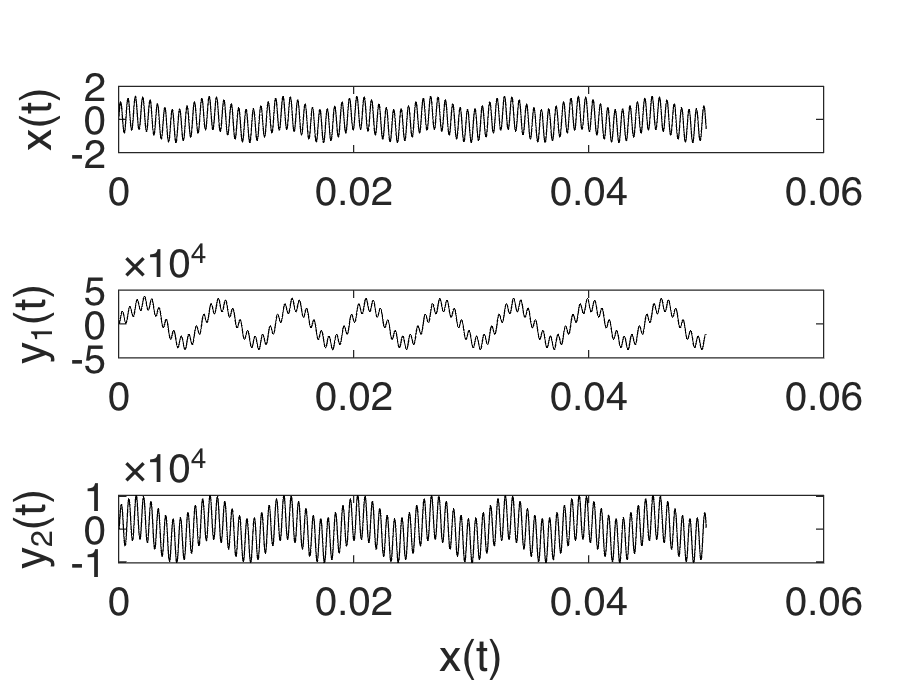

figure;
subplot(3,1,1), box on, hold on;
plot(t,x,'k');
set(gca,'FontSize',16);
ylabel('x(t)');
subplot(3,1,2), box on, hold on;
plot(t,y1,'k');
set(gca,'FontSize',16);
ylabel('y_1(t)');
subplot(3,1,3), box on, hold on;
plot(t,y2,'k');
set(gca,'FontSize',16);
ylabel('y_2(t)');
xlabel('x(t)');

绘制两个系统的幅频响应

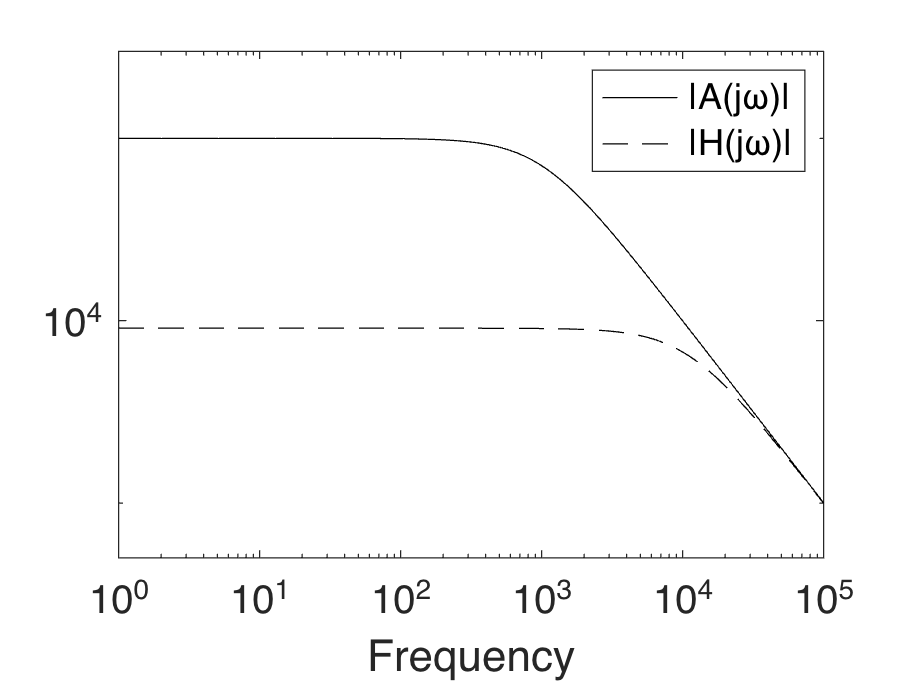

figure, box on, hold on;
plot(omg,abs(Aomg),'k');
plot(omg,abs(Homg),'k--');
set(gca,'YScale','log','XScale','log','FontSize',16);
set(gca,'YLim',[5e2,3e5],'XTick',10.^[0:5]);
legend('|A(j\omega)|','|H(j\omega)|');
xlabel('Frequency');